# Mehdi Muzaffari - MAE 674 - Project 1

## estimate states through ekf

clc;
clear;
close all;

## load simulate data

data = readtable('simulation');
time = data.Time;
theta1_true = data.Theta1;
theta1_dot_true = data.Theta1_Dot;
theta2_true = data.Theta2;
theta2_dot_true = data.Theta2_Dot;

time = downsample(time, 5);
theta1_true = downsample(theta1_true, 5);
theta1_dot_true = downsample(theta1_dot_true, 5);
theta2_true = downsample(theta2_true, 5);
theta2_dot_true = downsample(theta2_dot_true, 5);

## add noise to data

noise_std_theta1 = 0.05;
noise_std_theta1_dot = 0.03;
noise_std_theta2 = 0.04;
noise_std_theta2_dot = 0.02;

theta1_measured = theta1_true + noise_std_theta1 * randn(size(theta1_true));
theta1_dot_measured = theta1_dot_true + noise_std_theta1_dot * randn(size(theta1_dot_true));
theta2_measured = theta2_true + noise_std_theta2 * randn(size(theta2_true));
theta2_dot_measured = theta2_dot_true + noise_std_theta2_dot * randn(size(theta2_dot_true));

## simulation parameter

dt = 0.01;
num_steps = length(time);

theta1 = pi/4;
theta1_dot = 0;
theta2 = pi/6;
theta2_dot = 0;

x_hat = [pi/4; 0; pi/6; 0];
P = diag([0.01, 0.1, 0.01, 0.01]);
Q = diag([0.01, 0.01, 0.01, 0.01]);
R = diag([0.05, 0.05, 0.05, 0.05]);

## state transition matrix

syms x1 x2 x3 x4 g mu_M1 mu_M2 l1 l2 real

beta = x3 - x1;

dx1 = x2;
dx2 = (g * (mu_M2 * cos(beta) * sin(x3) - sin(x1)) + ...
       mu_M2 * l1 * sin(beta) * cos(beta) * x2^2 + ...
       mu_M2 * l2 * sin(beta) * x4^2) / ...
       (l1 * (mu_M1 + mu_M2 * sin(beta)^2));

dx3 = x4;
dx4 = -(l1 * sin(beta) * x2^2 + ...
        l2 * mu_M2 * sin(beta) * cos(beta) * x4^2 + ...
        g * cos(x1) * sin(beta)) / ...
        (l2 * (mu_M1 + mu_M2 * sin(beta)^2));

state_vector = [x1; x2; x3; x4];
equations = [dx1; dx2; dx3; dx4];

Jacobian = jacobian(equations, state_vector);
disp(Jacobian);

Jacobian Matrix at the given state:
         0    1.0000         0         0
  -10.1800         0    4.8686         0
         0         0         0    1.0000
    7.6171         0  -10.9824         0



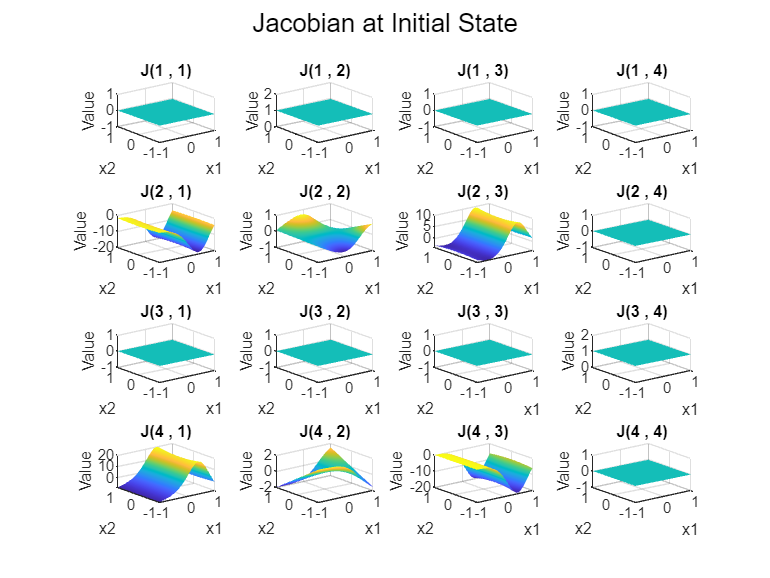

state = [pi/4; 0; pi/6; 0];
Jacobian_matrix = computeAndplotJacobian(state);

H = eye(4);

x_hat_history = zeros(4, num_steps);
P_hat_history = zeros(4, 4, num_steps);

x_hat_history(:, 1) = x_hat;
P_hat_history(:, :, 1) = P;

tic;
for k = 2:num_steps

z = [theta1_measured(k); theta1_dot_measured(k); theta2_measured(k); theta2_dot_measured(k)];

theta1 = x_hat(1);
theta1_dot = x_hat(2);
theta2 = x_hat(3);
theta2_dot = x_hat(4);

[theta1_ddot, theta2_ddot] = dynamic(theta1, theta1_dot, theta2, theta2_dot);

dt = 0.01;

theta1_dot = theta1_dot + theta1_ddot * dt;
theta2_dot = theta2_dot + theta2_ddot * dt;

theta1 = theta1 + theta1_dot * dt;
theta2 = theta2 + theta2_dot * dt;

x_hat = [theta1; theta1_dot; theta2; theta2_dot];

F = computejacobian(x_hat);
P = F * P * F' + Q;

z_hat = H * x_hat;
y = z - z_hat;

K = P * H' / (H * P * H' + R);
x_hat = x_hat + K * y;
P = (eye(size(P)) - K * H) * P;

x_hat_history(:, k) = x_hat;
P_hat_history(:, :, k) = P;

end

elapsed_time = toc;

## plots

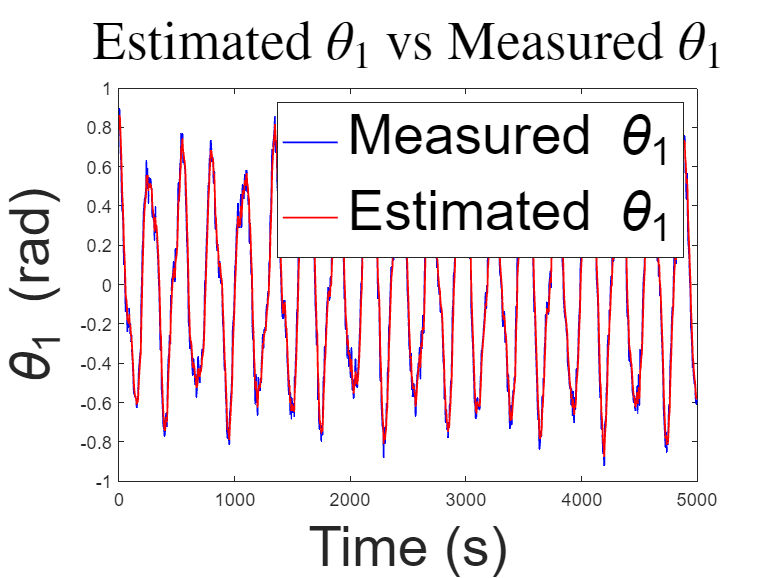

figure;
plot(time, theta1_measured, 'DisplayName', 'Measured \theta_1', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(1, :), 'DisplayName', 'Estimated \theta_1', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('\theta_1 (rad)', 'FontSize', 30);
legend ('FontSize', 30);
title('Estimated $\theta_1$ vs Measured $\theta_1$', 'Interpreter', 'Latex', 'FontSize', 30);

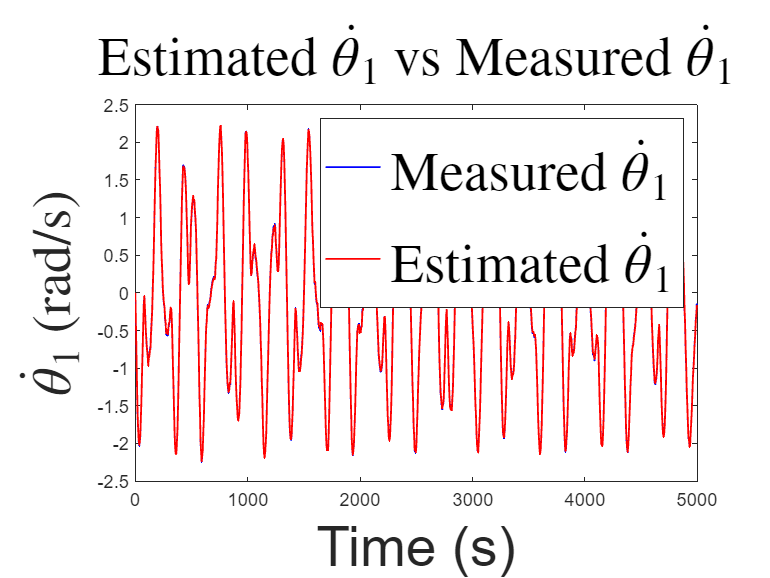

figure;
plot(time, theta1_dot_measured, 'DisplayName', 'Measured $\dot{\theta}_1$', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-')
hold on
plot(time, x_hat_history(2, :), 'DisplayName', 'Estimated $\dot{\theta}_1$', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-')
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('$\dot{\theta}_1$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 30);
legend('Interpreter', 'Latex', 'FontSize', 30);
title('Estimated $\dot{\theta}_1$ vs Measured $\dot{\theta}_1$', 'Interpreter', 'Latex', 'FontSize', 30);

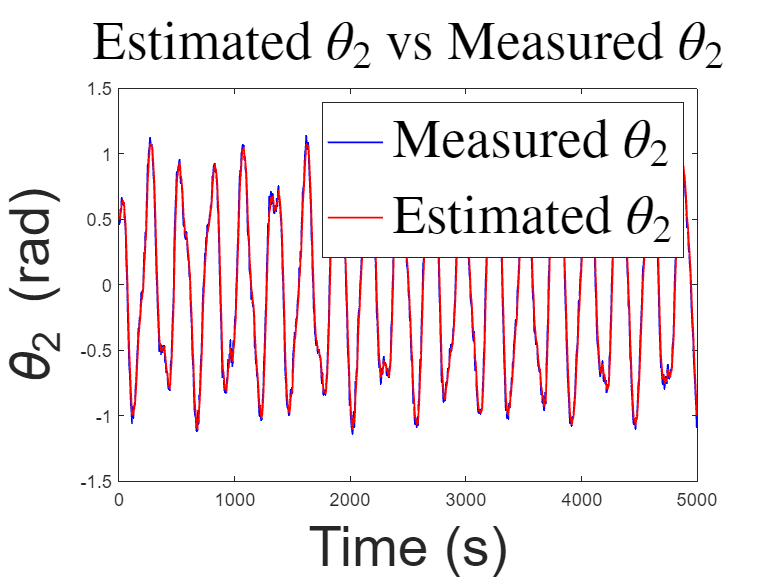

figure;
plot(time, theta2_measured, 'DisplayName', 'Measured $\theta_2$', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(3, :), 'DisplayName', 'Estimated $\theta_2$', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('\theta_2 (rad)', 'FontSize', 30);
legend('Interpreter', 'Latex', 'FontSize', 30);
title('Estimated $\theta_2$ vs Measured $\theta_2$', 'Interpreter', 'Latex', 'FontSize', 30);

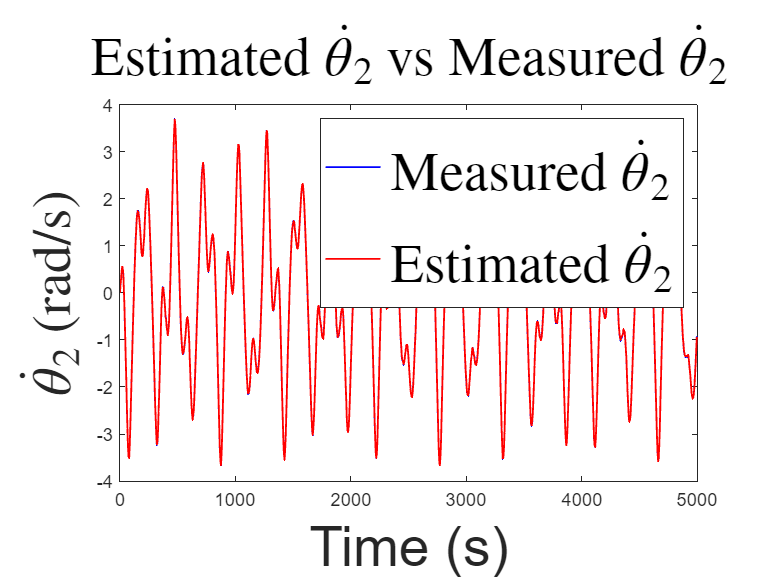

figure;
plot(time, theta2_dot_measured, 'DisplayName', 'Measured $\dot{\theta}_2$', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(4, :), 'DisplayName', 'Estimated $\dot{\theta}_2$', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('$\dot{\theta}_2$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 30);
legend('Interpreter', 'Latex', 'FontSize', 30);
title('Estimated $\dot{\theta}_2$ vs Measured $\dot{\theta}_2$', 'Interpreter', 'Latex', 'FontSize', 30);

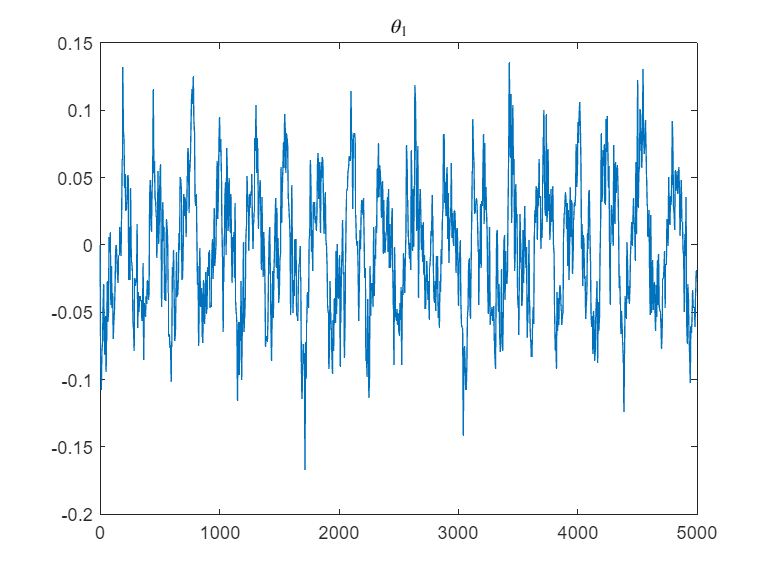

error1 = theta1_true' - x_hat_history(1, :);
plot(time, error1)
title('$\theta_1$', 'Interpreter', 'latex');

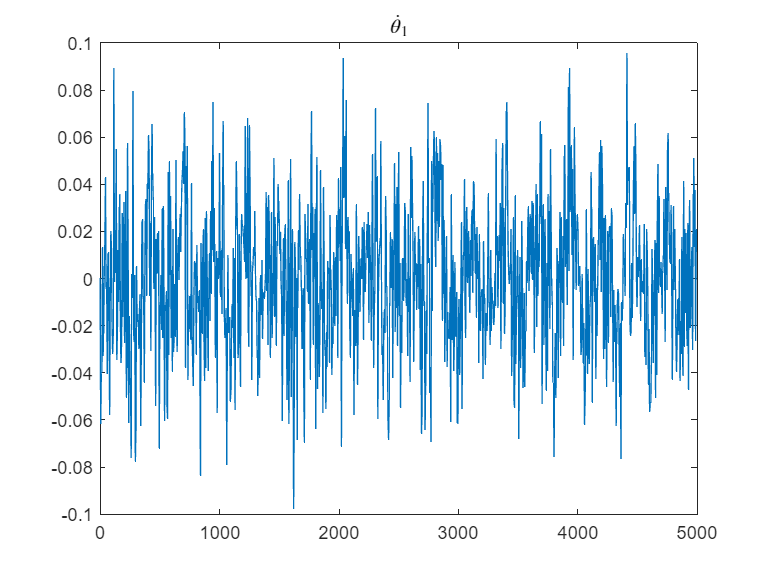


error2 = theta1_dot_true' - x_hat_history(2, :);
plot(time, error2)
title('$\dot{\theta}_1$', 'Interpreter', 'latex');

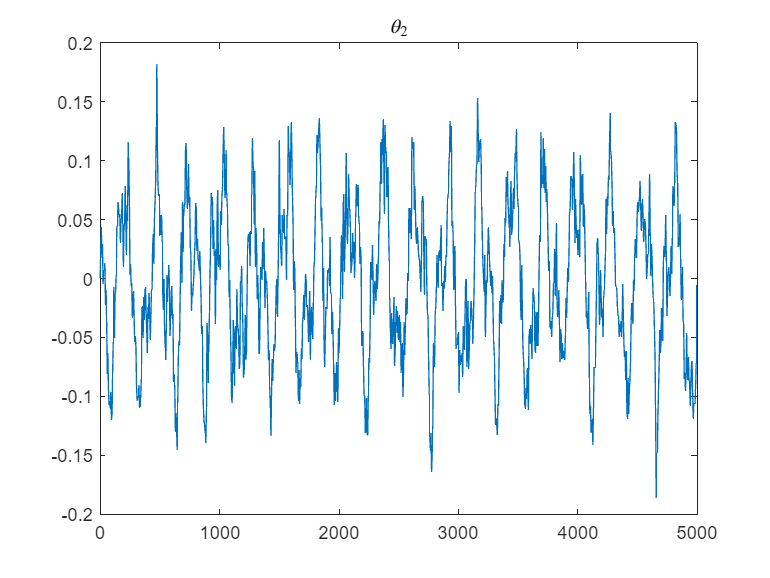


error3 = theta2_true' - x_hat_history(3, :);
plot(time, error3);
title('$\theta_2$', 'Interpreter', 'latex');

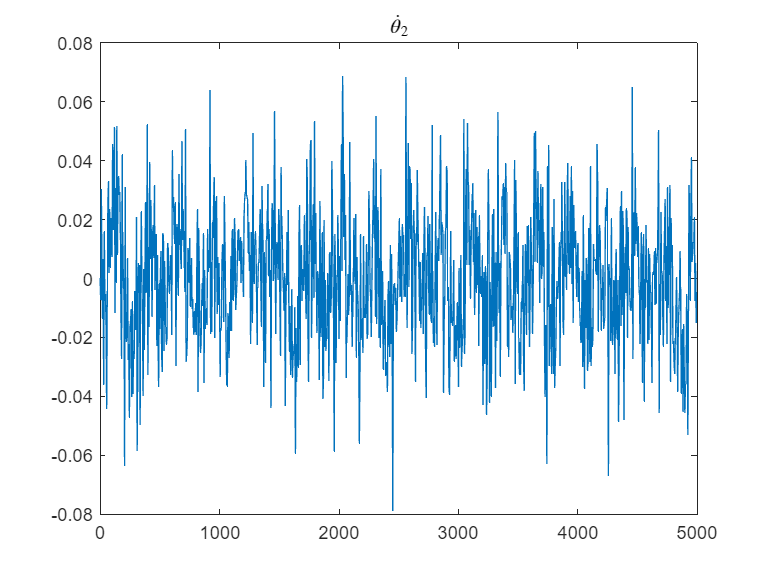


error4 = theta2_dot_true' - x_hat_history(4, :);
plot(time, error4);
title('$\dot{\theta}_2$', 'Interpreter', 'latex');

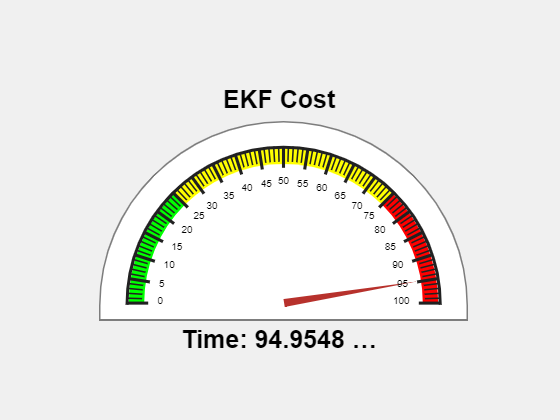

fig = uifigure('Name', 'EKF Cost');
gauge = uigauge(fig, 'semicircular');
gauge.Position = [100, 100, 400, 200];
gauge.Limits = [0 100];
gauge.Value = elapsed_time;
gauge.MajorTicks = 0:5:100;
gauge.FontSize = 10;

titleLabel = uilabel(fig, 'Text', 'EKF Cost');
titleLabel.Position = [180, 310, 200, 30];
titleLabel.HorizontalAlignment = 'center';
titleLabel.FontSize = 25;
titleLabel.FontWeight = 'bold';

valueLabel = uilabel(fig, 'Text', sprintf('Time: %.4f (s)', gauge.Value));
valueLabel.Position = [180, 70, 200, 30];
valueLabel.HorizontalAlignment = 'center';
valueLabel.FontSize = 25;
valueLabel.FontWeight = 'bold';

gauge.ScaleColors = [0 1 0; 1 1 0; 1 0 0];
gauge.ScaleColorLimits = [0 25; 25 75; 75 100];